Task 1:

Develop a matlab function that creates K samples of D-dimensional Gaussian data with arbitrary specified mean μ and covariance matrix Σ.

function [X_transformed, genMean, genCov] = generateGaussian(mu,sigma,K)
% mu = Dx1 matrix
% sigma = DxD matrix
% K = number of samples

% generating samples
rng(42); % for reproducability
dimension = length(mu);
samples = randn(K,dimension);

Xmean = mean(samples);
Xcov = cov(samples);

% Phi (φ) and lambda (λ)
% phi_X: eigenvectors (dxd)
% lambda_X: diagonal matrix of eigenvalues (dxd)
[phi_X, lambda_X] = eig(Xcov);

% center the mean
X_centered = samples - Xmean;

% whitening transform
T_W = phi_X * diag(1 ./ sqrt(diag(lambda_X)));  % Φ Λ^(-1/2)

% whitening
X_white = X_centered * T_W;

% check the whitening
X_white_cov = T_W' * (phi_X * lambda_X * phi_X') * T_W;
X_white_mean = mean(X_white);
disp("Sanity Check");
disp("Whitening Mean:");
disp(X_white_mean);
disp("Whitening Covariance:");
disp(X_white_cov);

% transform whitened samples to the target Gaussian distribution
T = chol(sigma, "lower");
X_transformed = X_white * T' + mu';

genMean = mean(X_transformed);
genCov = cov(X_transformed);
end

% test if the function is working
mu = [0; 4; 7];
sigma = [6.5000, 2.1651, 1.2500; 2.1651, 5.1250, 2.3816; 1.2500, 2.3816, 2.3750];
K = 10;
[test_samples,test_mean,test_cov] = generateGaussian(mu,sigma,K);

Sanity Check
Whitening Mean:
   1.0e-16 *

    0.7772    0.1110    0.3886

Whitening Covariance:
    1.0000    0.0000   -0.0000
   -0.0000    1.0000    0.0000
   -0.0000         0    1.0000



disp("Samples");

Samples


disp(test_samples);

   -0.4575    2.9970    7.2842
   -2.3015    2.4740    4.3252
   -1.4622    5.0758    5.7566
    1.6947    5.1014    7.6282
   -0.2534    5.8295    9.5393
   -0.2794    2.0911    6.8335
   -4.9342    2.8517    7.1504
    3.8587    6.8277    8.2342
    1.8983   -0.0399    5.2287
    2.2365    6.7916    8.0196



disp("Mean:");

Mean:


disp(test_mean);

    0.0000    4.0000    7.0000



disp("Covariance:");

Covariance:


disp(test_cov);

    6.5000    2.1651    1.2500
    2.1651    5.1250    2.3816
    1.2500    2.3816    2.3750



Task 2

Fully test your developed function to ensure that it indeed produces D-dimensional Gaussian data with the correct mean vector and covariance matrix.

% To prove the mean and covariance is correct,
% the answer should be around 10^-15 to 10^-16 difference
disp(max(abs(test_mean(:) - mu(:))));

   8.8818e-16



disp(max(max(abs(test_cov - sigma))));

   4.4409e-15



Task 3

Discuss why, when K < ∞, the Matlab’s computed covariance matrix for your Gaussian generated data will not exactly match the covariance you prescribed.

%{
Because Matlab randn takes random samples from Gaussian distribution (0 mean and 1 standard deviation). 
When we are using cov() and mean(), we are only calculating from finite K samples from the distribution.
Therefore, the mean and covariance calculated in the function will not be
the true mean and true covariance as long as K is less than infinity.
%}

Task 4

Use your created function to create 1000 data samples for each of the three classes A, B, and C where each is described by a 3-dimensional Gaussian distributions with their sufficient statistics given as:


$$\mu_A = \left[\matrix{0 \cr 4 \cr 7}\right], \mu_B = \left[\matrix{10 \cr 5 \cr 5}\right], \mu_C = \left[\matrix{-2 \cr -5 \cr -5}\right]$$



$$\Sigma_A = \left[\matrix{6.5000 & 2.1651 & 1.2500 \cr 2.1651 & 5.1250 & 2.3816 \cr 1.2500 & 2.3816 & 2.3750}\right], \Sigma_B = \left[\matrix{3.0184 & 0.4331 & -1.4481 \cr 0.4331 & 0.9436 & -0.6456 \cr -1.4481 & -0.6456 & 1.2880}\right], \Sigma_C = \left[\matrix{6.8928 & -1.3750 & 3.1945 \cr -1.3750 & 3.3572 & 0.6945 \cr 3.1945 & 0.6945 & 3.7500}\right]$$


The data you produce must exactly match the above means and covariances, i.e., when you run Matlab’s cov() function you should exactly get $\Sigma_A ,\Sigma_B \;\mathrm{and}\;\Sigma_C$and not covariances that are simply close to these stated covariances.

mu_A = [0; 4; 7];
sigma_A = [6.5000, 2.1651, 1.2500; 2.1651, 5.1250, 2.3816; 1.2500, 2.3816, 2.3750];
mu_B = [10; 5; 5];
sigma_B = [3.0184, 0.4331, -1.4481; 0.4331, 0.9436, -0.6456; -1.4481, -0.6456, 1.2880];
mu_C = [-2; -5; -5];
sigma_C = [6.8928, -1.3750, 3.1945; -1.3750, 3.3572, 0.6945; 3.1945, 0.6945, 3.7500];
K = 1000;
disp("Class A")

Class A


[samples_A,mean_A,cov_A] = generateGaussian(mu_A,sigma_A,K);

Sanity Check
Whitening Mean:
   1.0e-16 *

    0.1643    0.2842   -0.1954

Whitening Covariance:
    1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000         0    1.0000



disp("Samples");

Samples


disp(samples_A);

    1.5897    6.8953    8.4253
   -2.5198    2.2417    5.5531
    2.0402    3.3634    5.5784
   -0.8812    2.7984    6.2683
    2.2383    5.7886    8.5928
    3.9406    5.7737    7.9694
    2.7400   10.1867   10.2576
   -1.9663    4.0086    6.0089
    0.4154    4.8774    7.0325
    1.7224    4.7952    6.2826
   -0.4147    3.1509    7.4326
    0.1695    5.2623    5.2266
   -5.1405   -0.0558    3.8633
    3.1241    2.0833    6.4191
   -1.0540    3.3886    8.1331
   -2.9836    3.6284    7.7881
   -4.0352    0.2387    5.9963
    3.9406    2.5626    6.4563
   -1.6794    4.8443    8.0803
    2.0438    3.7690    6.4781
   -1.1781    0.4229    6.4240
    0.7724    2.2496    7.9096
    1.4041    3.4922    7.1054
    0.8245    7.1022    7.9712
   -2.3669    2.0219    5.3257
    2.0985    4.5955    8.0103
    0.2953    7.4460    7.9162
   -0.0321    5.5550    7.1443
   -1.0420    5.4435    9.9425
   -1.3106   -0.5157    5.2020
    6.2939    8.6691    9.2559
   -2.3094    6.8672    8.3332
    1.73

disp("Mean:");

Mean:


disp(mean_A);

   -0.0000    4.0000    7.0000



disp("Covariance:");

Covariance:


disp(cov_A);

    6.5000    2.1651    1.2500
    2.1651    5.1250    2.3816
    1.2500    2.3816    2.3750



disp("Class B")

Class B


[samples_B,mean_B,cov_B] = generateGaussian(mu_B, sigma_B, K);

Sanity Check
Whitening Mean:
   1.0e-16 *

    0.1643    0.2842   -0.1954

Whitening Covariance:
    1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000         0    1.0000



disp("Samples");

Samples


disp(samples_B);

   11.0833    6.2139    3.9895
    8.2829    4.3425    5.7262
   11.3903    4.6106    3.9550
    9.3995    4.5076    5.4041
   11.5253    5.6855    4.4174
   12.6853    5.5916    3.6124
   11.8672    7.6274    3.1384
    8.6600    5.1046    4.9985
   10.2831    5.3713    4.4937
   11.1737    5.2675    3.7604
    9.7174    4.6414    5.7471
   10.1155    5.5561    3.3952
    6.4970    3.4489    6.5987
   12.1289    3.9824    4.7112
    9.2818    4.7805    6.1961
    7.9668    4.9866    6.4299
    7.2502    3.5240    7.3215
   12.6853    4.1550    4.2822
    8.8556    5.4638    5.6618
   11.3928    4.7919    4.2567
    9.1972    3.4600    6.6787
   10.5264    4.1773    6.0994
   10.9568    4.7009    4.9057
   10.5619    6.3456    3.8566
    8.3871    4.2363    5.6620
   11.4300    5.1589    4.6939
   10.2012    6.5266    3.8127
    9.9781    5.6973    4.3629
    9.2899    5.6992    6.2240
    9.1069    3.0469    6.4849
   14.2889    6.7664    2.3146
    8.4262    6.4011    5.0314
   11.18

disp("Mean:");

Mean:


disp(mean_B);

    10     5     5



disp("Covariance:");

Covariance:


disp(cov_B);

    3.0184    0.4331   -1.4481
    0.4331    0.9436   -0.6456
   -1.4481   -0.6456    1.2880



disp("Class C")

Class C


[samples_C,mean_C,cov_C] = generateGaussian(mu_C, sigma_C, K);

Sanity Check
Whitening Mean:
   1.0e-16 *

    0.1643    0.2842   -0.1954

Whitening Covariance:
    1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000         0    1.0000



disp("Samples");

Samples


disp(samples_C);

   -0.3630   -3.3471   -3.3121
   -4.5948   -5.2513   -7.1756
    0.1009   -6.5203   -5.9257
   -2.9075   -5.5787   -5.9310
    0.3049   -4.5871   -2.7460
    2.0580   -5.4237   -2.9459
    0.8216   -1.1501   -1.3485
   -4.0249   -4.0409   -6.7538
   -1.5722   -4.4670   -4.9724
   -0.2263   -5.1685   -5.4298
   -2.4270   -5.5097   -4.4919
   -1.8254   -4.0259   -7.2040
   -7.2936   -5.9048   -9.5798
    1.2171   -8.1161   -4.4177
   -3.0853   -5.0014   -3.9119
   -5.0725   -3.8665   -4.9406
   -6.1554   -6.1935   -6.8118
    2.0579   -8.1104   -4.1995
   -3.7293   -3.4805   -4.3925
    0.1047   -6.1827   -4.9439
   -3.2132   -7.4226   -5.4694
   -1.2046   -6.8385   -3.4338
   -0.5541   -6.1046   -4.3683
   -1.1509   -2.8036   -4.1058
   -4.4374   -5.5092   -7.3584
    0.1610   -5.5176   -3.2781
   -1.6959   -2.2597   -4.3856
   -2.0331   -3.6834   -5.0858
   -3.0730   -3.2878   -2.1297
   -3.3496   -8.1437   -6.7814
    4.4813   -4.1404   -1.1854
   -4.3782   -1.4830   -4.6085
   -0.21

disp("Mean:");

Mean:


disp(mean_C);

   -2.0000   -5.0000   -5.0000



disp("Covariance:");

Covariance:


disp(cov_C);

    6.8928   -1.3750    3.1945
   -1.3750    3.3572    0.6945
    3.1945    0.6945    3.7500




% Comparing to true mean and true covariance
disp("Comparing True and Calculated Mean and Covariance")

Comparing True and Calculated Mean and Covariance


disp("Mean diff (Class A):"); disp(max(abs(mean_A(:) - mu_A(:))));

Mean diff (Class A):
   1.7764e-15



disp("Cov diff (Class A):"); disp(max(max(abs(cov_A - sigma_A))));

Cov diff (Class A):
   2.6645e-15



disp("Mean diff (Class B):"); disp(max(abs(mean_B(:) - mu_B(:))));

Mean diff (Class B):
     0



disp("Cov diff (Class B):"); disp(max(max(abs(cov_B - sigma_B))));

Cov diff (Class B):
   2.2204e-15



disp("Mean diff (Class C):"); disp(max(abs(mean_C(:) - mu_C(:))));

Mean diff (Class C):
   1.7764e-15



disp("Cov diff (Class C):"); disp(max(max(abs(cov_C - sigma_C))));

Cov diff (Class C):
   2.2204e-15



Task 5

You need to create your own function to generated the required Gaussian data using Matlab’s randn() function which produces N(0, 1) Gaussian data samples. Once you have created your function you can then compare you results to the results produced via Matlab’s mvnrnd() function. Are the results similar? Why are they not exactly the same?Which function exactly produced data sets with the required $\Sigma_A ,\Sigma_B \;\mathrm{and}\;\Sigma_C$covariances? Why is it important to be able to generate data with exactly the convariance that you require (and not just covariances that are “close”) ?

disp("Comparing generateGaussian vs mvnrnd")

Comparing generateGaussian vs mvnrnd


rng(42); % same seed as the earlier function
mvn_A = mvnrnd(mu_A', sigma_A, K);
mvn_B = mvnrnd(mu_B', sigma_B, K);
mvn_C = mvnrnd(mu_C', sigma_C, K);

mvnMean_A = mean(mvn_A); mvnCov_A = cov(mvn_A);
mvnMean_B = mean(mvn_B); mvnCov_B = cov(mvn_B);
mvnMean_C = mean(mvn_C); mvnCov_C = cov(mvn_C);

disp("mvnrnd Mean diff (Class A):"); disp(max(abs(mvnMean_A(:) - mu_A(:))));

mvnrnd Mean diff (Class A):
    0.0268



disp("mvnrnd Cov diff (Class A):"); disp(max(max(abs(mvnCov_A - sigma_A))));

mvnrnd Cov diff (Class A):
    0.5707



disp("mvnrnd Mean diff (Class B):"); disp(max(abs(mvnMean_B(:) - mu_B(:))));

mvnrnd Mean diff (Class B):
    0.0512



disp("mvnrnd Cov diff (Class B):"); disp(max(max(abs(mvnCov_B - sigma_B))));

mvnrnd Cov diff (Class B):
    0.0971



disp("mvnrnd Mean diff (Class C):"); disp(max(abs(mvnMean_C(:) - mu_C(:))));

mvnrnd Mean diff (Class C):
    0.1318



disp("mvnrnd Cov diff (Class C):"); disp(max(max(abs(mvnCov_C - sigma_C))));

mvnrnd Cov diff (Class C):
    0.1873



Task 6

Use matlab’s ellipsoid() function to create contour intervals for Classes A, B, and C at one, two, and three standard deviations from $\mu_A ,\mu_B \;\mathrm{and}\;\mu_C$and also on the same plot the principal axes of each generated Gaussian contour ellipses using matlab’s line() function.

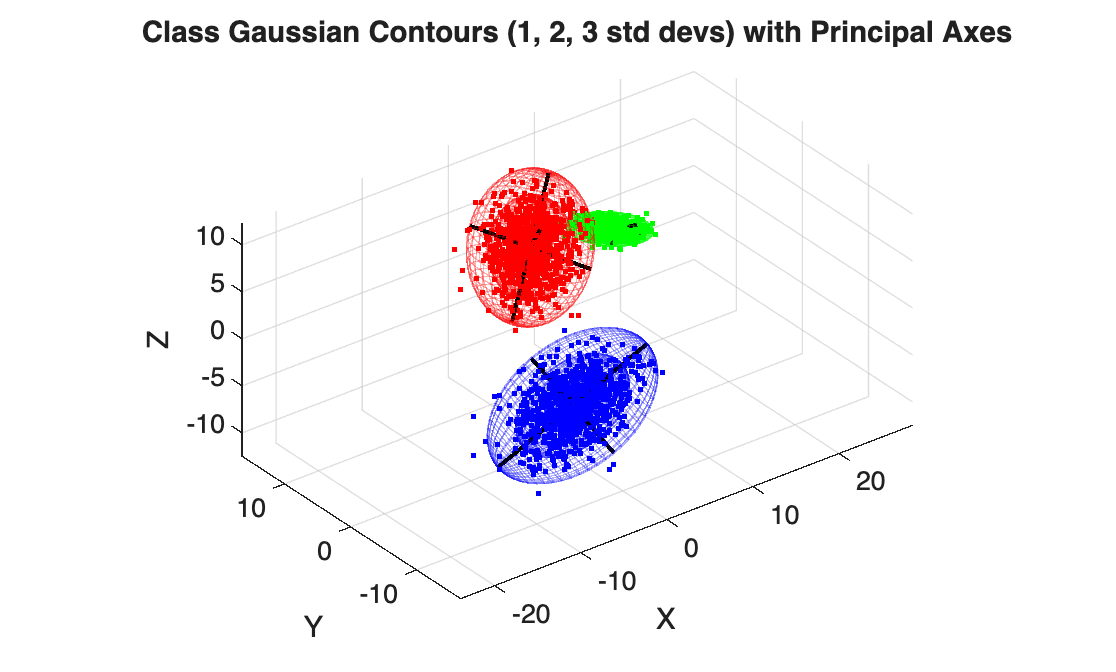

% Function for ellipsoid
function plotGaussianEllipsoid(mu, sigma, color, nStdList)
% mu = Dx1
% sigma = DxD
% color = plot color
% nStdList = e.g. [1 2 3]

[phi, lambda] = eig(sigma);
eigVals = diag(lambda);

hold on;

for n = nStdList
    % generate unit sphere
    [X, Y, Z] = ellipsoid(0,0,0,1,1,1,30);
    pts = [X(:), Y(:), Z(:)]; % (numPoints x 3)

    % scale by n*sqrt(eigenvalues), rotate by eigenvectors, shift by mu
    scaled = pts * diag(n * sqrt(eigVals));
    rotated = scaled * phi';
    shifted = rotated + mu';

    % reshape back to grid for surf plotting
    Xe = reshape(shifted(:,1), size(X));
    Ye = reshape(shifted(:,2), size(Y));
    Ze = reshape(shifted(:,3), size(Z));

    surf(Xe, Ye, Ze, 'FaceColor', 'none', 'EdgeColor', color, 'EdgeAlpha', 0.3);
end

% principal axes: one line per eigenvector, length = 3*sqrt(eigenvalue) 
% (using 3 std so the longest ellipsoid is fully spanned)
for i = 1:length(eigVals)
    axisVec = phi(:,i) * 3 * sqrt(eigVals(i));
    p1 = mu - axisVec;
    p2 = mu + axisVec;
    line([p1(1) p2(1)], [p1(2) p2(2)], [p1(3) p2(3)], 'Color', 'k', 'LineWidth', 1.5);
end

end

% Class Gaussian Contour with 1,2, and 3 standard deviations
figure;
% Red = Class A; Green = Class B; Blue = Class C;
plotGaussianEllipsoid(mu_A, sigma_A, 'r', [1 2 3]);
plotGaussianEllipsoid(mu_B, sigma_B, 'g', [1 2 3]);
plotGaussianEllipsoid(mu_C, sigma_C, 'b', [1 2 3]);
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Class Gaussian Contours (1, 2, 3 std devs) with Principal Axes');
grid on; axis equal; view(3);

scatter3(samples_A(:,1), samples_A(:,2), samples_A(:,3), 5, 'r', 'filled');
scatter3(samples_B(:,1), samples_B(:,2), samples_B(:,3), 5, 'g', 'filled');
scatter3(samples_C(:,1), samples_C(:,2), samples_C(:,3), 5, 'b', 'filled');

Task 7:

Use the provided vol3D.m function to create a regular set of uniformly spaced grid points withing the 3D volume of the Class A, B, and C Gaussian distributions. This function will return a vector of 3D data points within the volume you have specified and you can use the matlab plot3d() function to plot these data points.

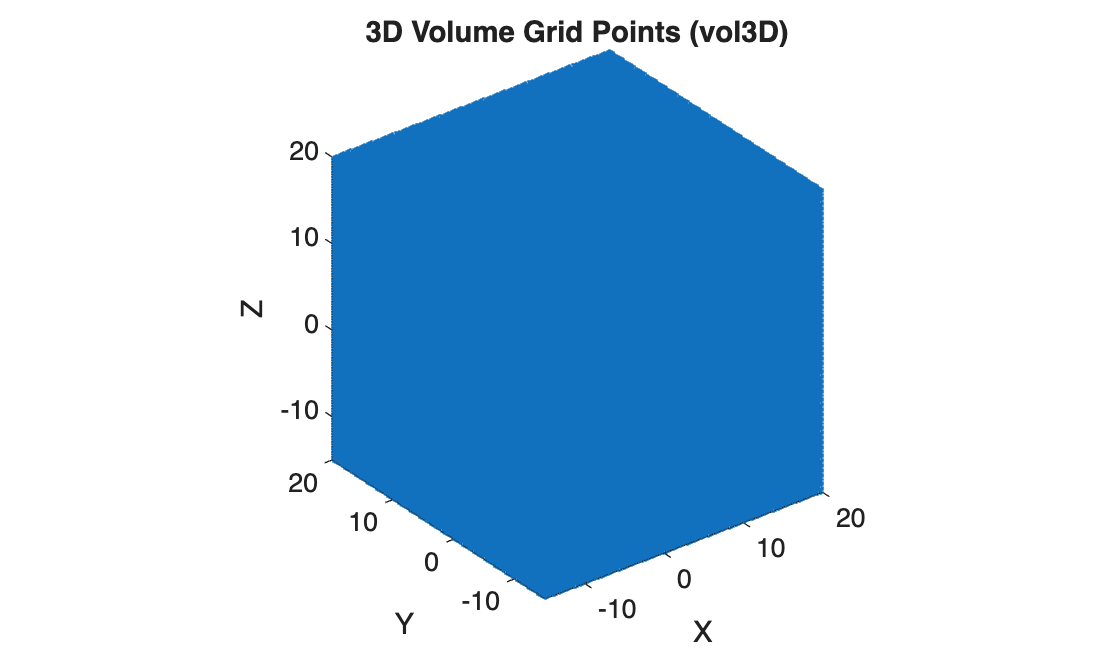

allSamples = [samples_A; samples_B; samples_C];

% buffer = 2;
% xMin = min(allSamples(:,1)) - buffer; xMax = max(allSamples(:,1)) + buffer;
% yMin = min(allSamples(:,2)) - buffer; yMax = max(allSamples(:,2)) + buffer;
% zMin = min(allSamples(:,3)) - buffer; zMax = max(allSamples(:,3)) + buffer;

% Vaxis = [xMin xMax yMin yMax zMin zMax];
Vaxis = [-15 20 -15 20 -15 20];
Num = 120;

gridPoints = vol3D(Vaxis, Num);

% visualize the grid
figure;
plot3(gridPoints(:,1), gridPoints(:,2), gridPoints(:,3), '.', 'MarkerSize', 1);
xlabel('X'); ylabel('Y'); zlabel('Z');
title('3D Volume Grid Points (vol3D)');
grid on; axis equal;

Task 8:

Apply the class discriminant function to this set of vol3D() data points and assign each point to its respective class based on Bayes classification.

Discriminant Function: $g_i(\mathbf{x}) = -\frac{1}{2} (\mathbf{x} - {\mu}_i)^T \mathbf{\Sigma}_i^{-1} (\mathbf{x} - {\mu}_i) - \frac{1}{2} \ln |\mathbf{\Sigma}_i|$

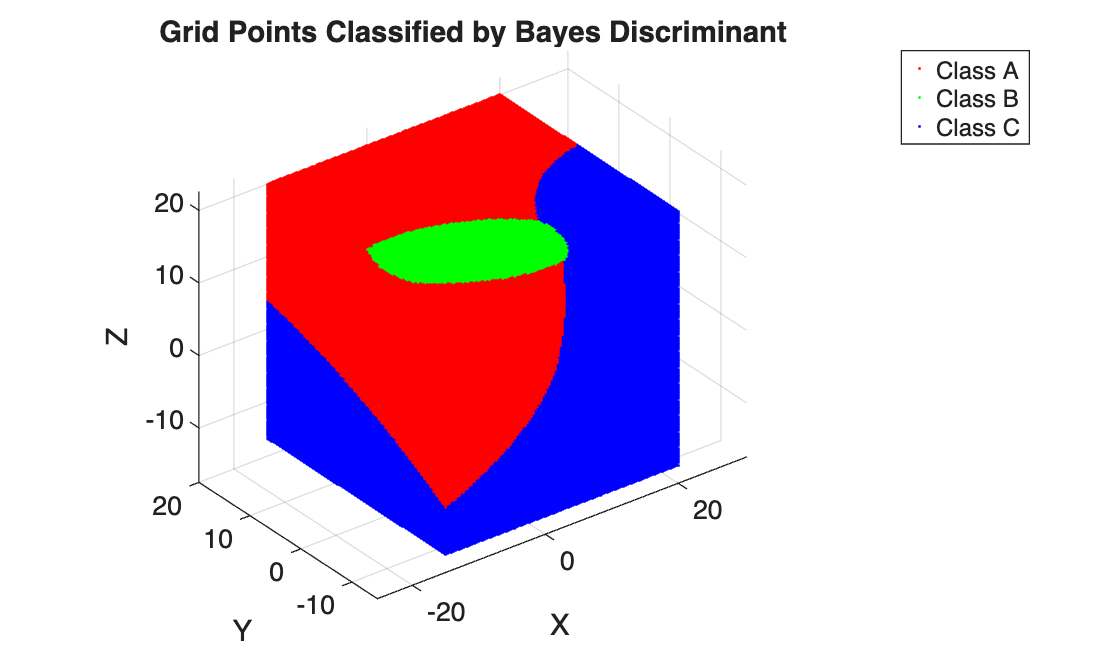

% 
% Bayes Discriminant function
function g = discriminant(X, mu, sigma)
% X = N x D matrix of points
% mu = D x 1 mean vector
% sigma = D x D covariance matrix
% returns g = N x 1 vector of discriminant scores

D = size(X,1);
Xc = X - mu';

invSigma = inv(sigma);
logDetSigma = log(det(sigma));

% vectorized Mahalanobis distance
quadForm = sum((Xc * invSigma) .* Xc, 2);

g = -0.5 * quadForm - 0.5 * logDetSigma;

end

g_A = discriminant(gridPoints, mu_A, sigma_A);
g_B = discriminant(gridPoints, mu_B, sigma_B);
g_C = discriminant(gridPoints, mu_C, sigma_C);

allG = [g_A, g_B, g_C]; % N x 3
% Nx1 output
% 1 = Class A; 2 = Class B; 3 = Class C
[~, classLabels] = max(allG, [], 2);

% visualization
figure;
colors = {'r','g','b'};
hold on;
for c = 1:3
    mask = classLabels == c;
    plot3(gridPoints(mask,1), gridPoints(mask,2), gridPoints(mask,3), ...
        '.', 'Color', colors{c}, 'MarkerSize', 2);
end
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Grid Points Classified by Bayes Discriminant');
grid on; axis equal; view(3);
legend('Class A','Class B','Class C');

Task 9

Draw the classification boundary by identifying the points in the 3D volume for which the difference between discriminate functions is less than a defined threshold, i.e., $\left|g_1 \left(x\right)-g_2 \left(x\right)\right|<\varepsilon$

As you are dealing with real data and sample data points within the 3D volume the theoretical Bayes boundary, which occurs at $g_1 \left(x\right)-g_2 \left(x\right)$ = 0, is not directly accessible via the data, i.e., the tested 3D volume data points are highly unlikely to fall exactly on the class decision boundaries. 

Instead, the above approach allows you to identify a sufficiently close neighborhood of the ideal Bayes boundary by the use of the $\varepsilon$ term. In general, and $\varepsilon \in \left\lbrack {10}^{-4} ,{10}^{-2} \right\rbrack$should work reasonably well depending on the sampling density you used to produced your vol3D data samples.

sortedG = sort(allG, 2, 'descend');
topGap = sortedG(:,1) - sortedG(:,2);

epsilon = 0.1;
boundaryMask = abs(topGap) < epsilon;
boundaryPoints = gridPoints(boundaryMask, :);

fprintf("Number of boundary points found: %d\n", size(boundaryPoints,1));

Number of boundary points found: 3160


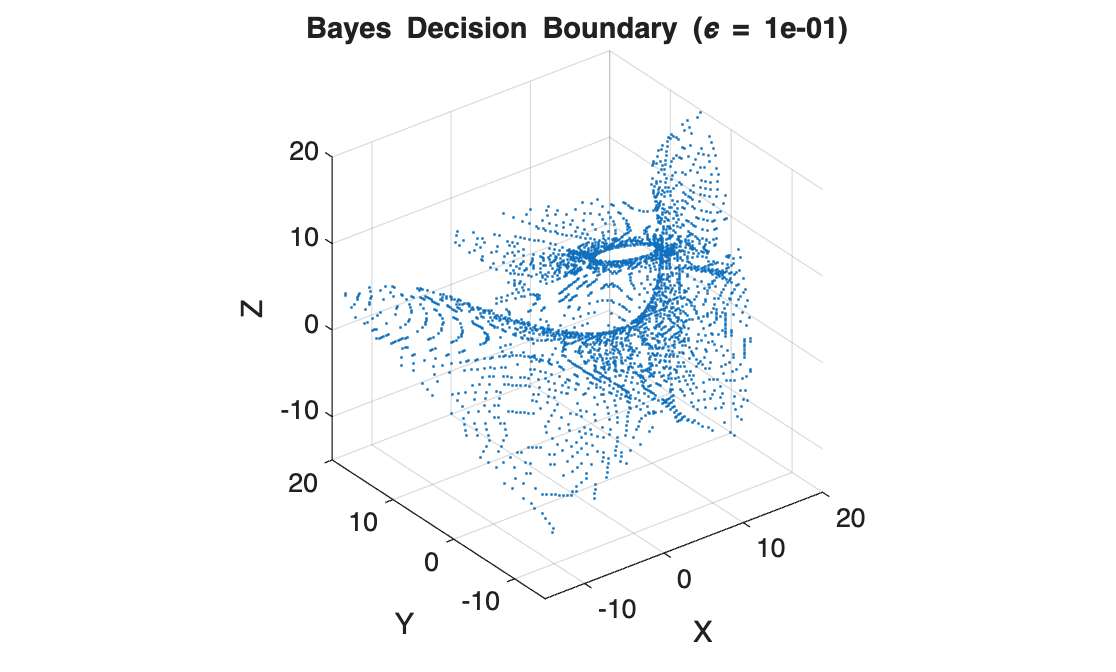


% visualization
figure;
plot3(boundaryPoints(:,1), boundaryPoints(:,2), boundaryPoints(:,3), '.', 'MarkerSize', 3);
xlabel('X'); ylabel('Y'); zlabel('Z');
title(sprintf('Bayes Decision Boundary (\\epsilon = %.0e)', epsilon));
grid on; axis equal; view(3);


disp(min(topGap));

   4.3490e-05



disp(prctile(topGap, [1 5 10])); % see how many points are "close-ish"

    0.5622    2.8716    5.9638



for eps_test = [1e-2, 5e-2, 1e-1, 3e-1, 5e-1]
    n = sum(topGap < eps_test);
    fprintf("epsilon=%.0e -> %d points\n", eps_test, n);
end

epsilon=1e-02 -> 313 points
epsilon=5e-02 -> 1565 points
epsilon=1e-01 -> 3160 points
epsilon=3e-01 -> 9238 points
epsilon=5e-01 -> 15349 points


Task 10

Your produced 3-class boundary should look identical to the boundary image provided on the ECE 537 Brightspace page. The only difference that should arise should be due solely to the sampling density and $\varepsilon$ threshold used. Any significant difference is the result of errors within your code.

% Task 10